# Evaluation of simpleStroop Test Data

This script shows a basic evaluation of the simpleStroop Test Data for 

% Ask for data to be analysed
clearvars;
participantName = "../../data/ParticipantXYZ";  
% FURTHER PRACTICE: Change the string to use a Live Control which allows for different 
% filenames to be analyzed

% Get data and change data types to categoricals for easier handling
[filepath, filename, ~] = fileparts(participantName);
results = readtable(fullfile(filepath, [filename + '.csv']));
results.trialSeqWord = categorical(results.trialSeqWord);
results.trialSeqColor = categorical(results.trialSeqColor);
results.responseColorIdx = categorical(results.responseColorIdx);

% TASK 1: Change the comment below into a textual description
% <H1> Task description</H1>
% During this test the participant was presented with a GUI showing color words. The letters of the words were themselves presented in different colors.
% <<INSERT A SCREENSHOT OF THE APP AS WELL>>
% The task of the participant was to use a button to select the color in which letters were printed.In the example shown the correct answer would have been "Blue". Independent of this response times were measured.

## Results

### Overall Statistics

% Split data into trials where word and color matches, and where they do
% not
matchingIdx = results.trialSeqWord == results.trialSeqColor;
matchedTrials = results(matchingIdx, :);
unmatchedTrials = results(~matchingIdx, :);

Each color word and each color was presented the same number of times. The overall number of trails was 

numTrails = length(results.Var1)

numTrails = 90

Within these trials there were 

numMatchedTrails = length(matchedTrials.Var1)

numMatchedTrails = 31

trails where the color word matched the color in which letters were printed, and

numUnmatchedTrails = length(unmatchedTrials.Var1)

numUnmatchedTrails = 59

trials where they did differ. 

### Errorrate

results.correctAnswers = results.responseColorIdx == results.trialSeqColor;
correctAnswers = sum(results.correctAnswers);
falseAnswers = numTrails - correctAnswers;


The overall number of responses and their split into correct and false responses is shown below.

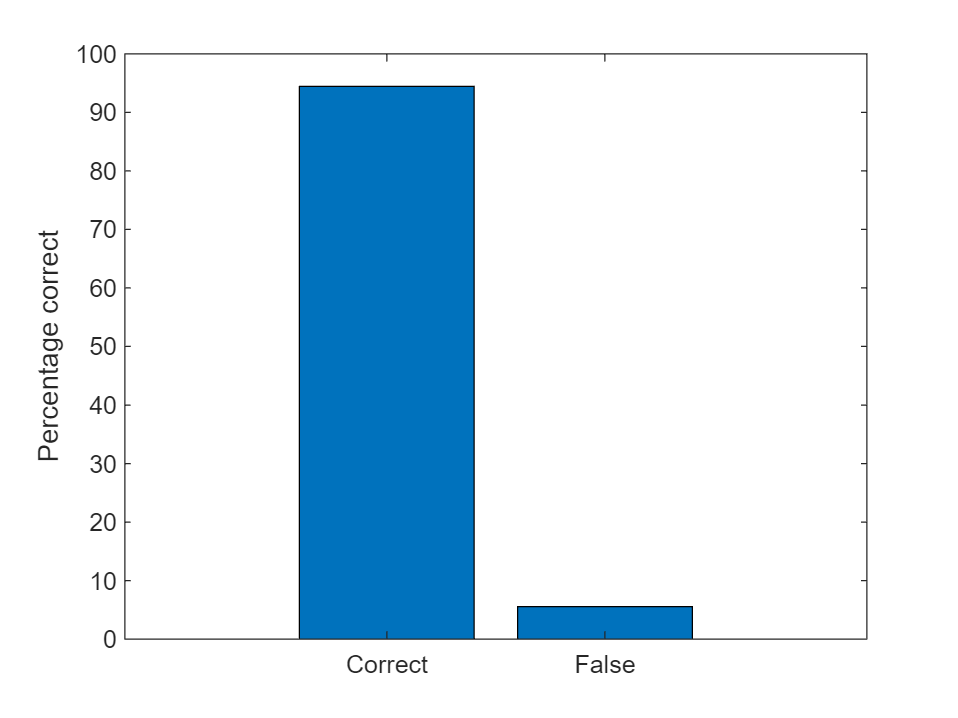

bar([correctAnswers, falseAnswers]./numTrails * 100)
xticklabels({'Correct'; 'False'})
ylabel("Percentage correct")

### Interactive errorrate analysis

Now let us check if fast responses are more likely to lead to response errors. For this we first define a response time threshold

responseTimeThreshold = 1; % TASK 2: Insert a Live Control slider to produce an interactive analysis

With that find the responses which were quicker than this threshold. 

quickResponses = results(results.responseTime <= responseTimeThreshold, :);


There were  

numQuickResponses = length(quickResponses.Var1)

numQuickResponses = 57

trials where to participant responded quicker.

Looking into those quicker responses we see

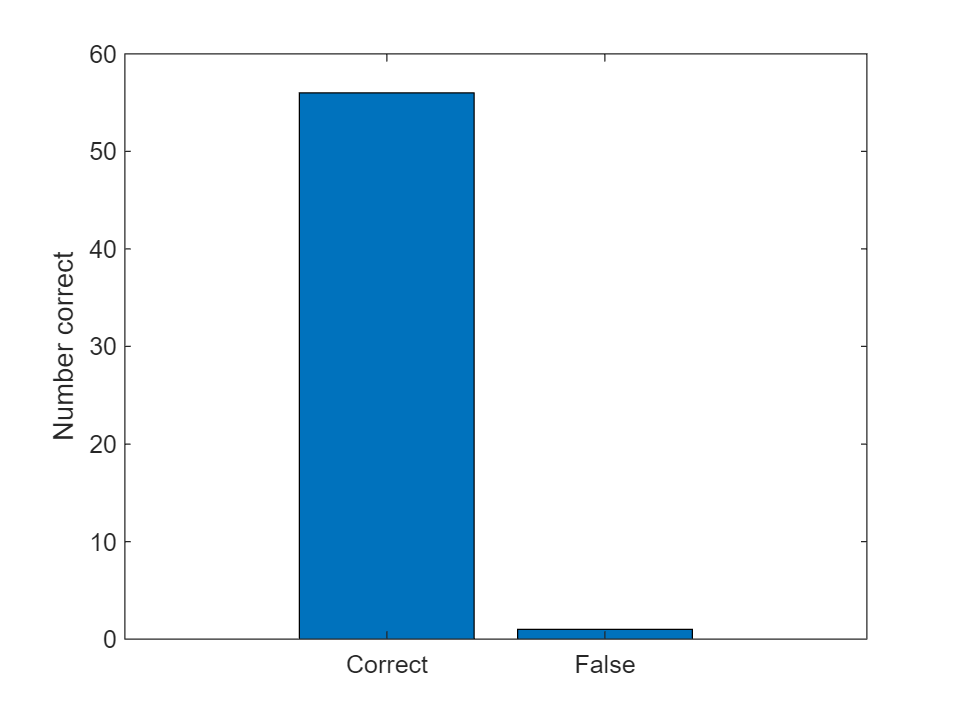

correctQuickAnswers = sum(quickResponses.responseColorIdx == quickResponses.trialSeqColor);
falseQuickAnswers = numQuickResponses - correctQuickAnswers;
bar([correctQuickAnswers, falseQuickAnswers])
xticklabels({'Correct'; 'False'})
ylabel("Number correct")

### Confusion analysis

Confusion charts of the overall data show which confusions occured. Below this is shown for all trials. 

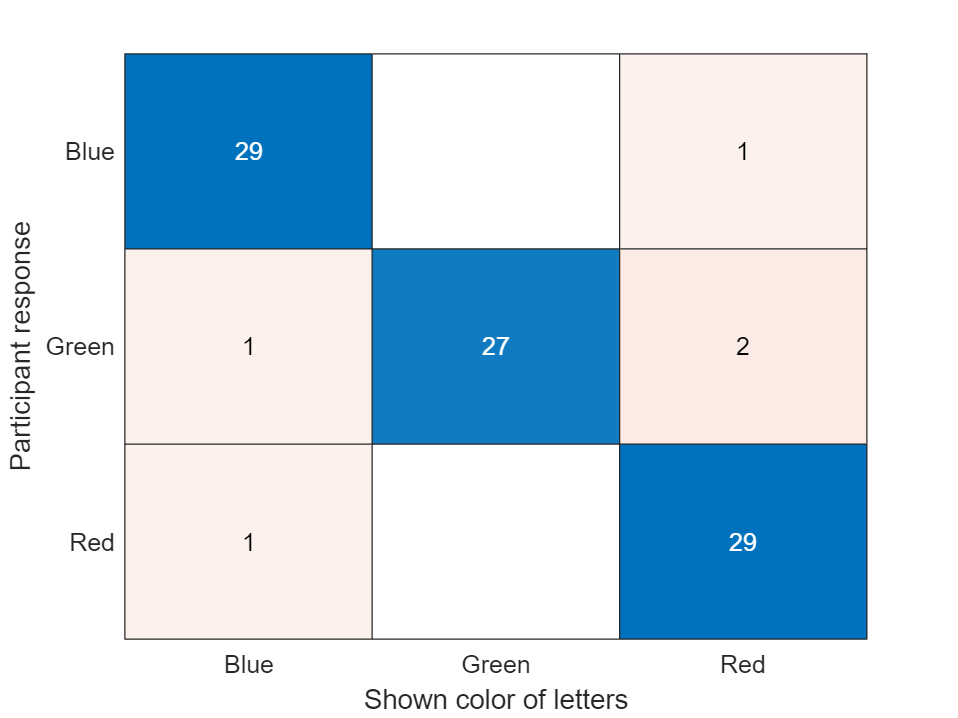

confusionchart(results.trialSeqColor, results.responseColorIdx)
xlabel('Shown color of letters')
ylabel('Participant response')

### Response times

#### Graphical comparison

A comparison of response times between the matching and the unmatched tasks is shown below

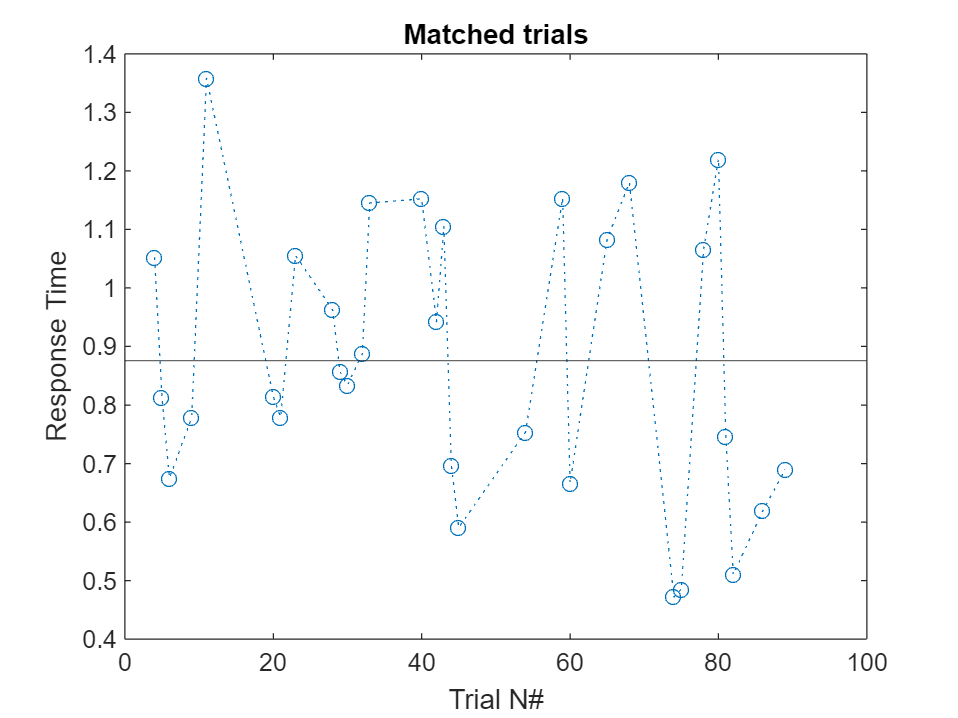

tiledlayout(2, 1);
plot(matchedTrials.Var1, matchedTrials.responseTime, 'o:')
yline(mean(matchedTrials.responseTime))
xlabel('Trial N#')
ylabel('Response Time')
title('Matched trials')
nexttile

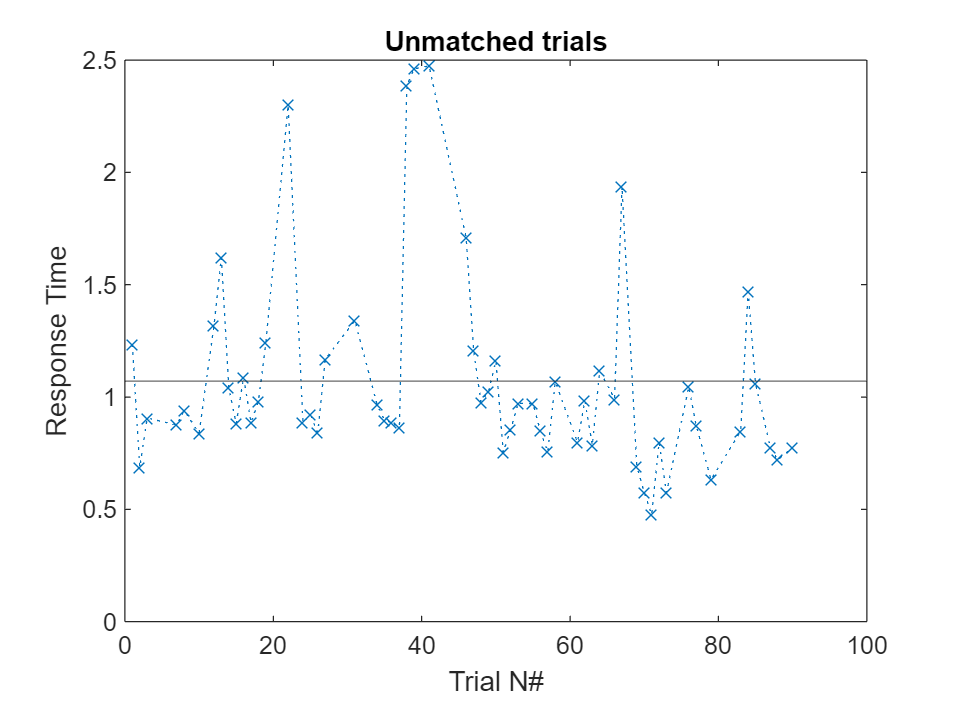

title('Unmatched trials')
plot(unmatchedTrials.Var1, unmatchedTrials.responseTime, 'x:')
yline(mean(unmatchedTrials.responseTime))
xlabel('Trial N#')
ylabel('Response Time')
title('Unmatched trials')

#### Distribution of response times 

In addition to the graphical comparison it is interesting to subject the data to some statistical testing. Before we do so we should get an idea how the distribution of the data looks.

% TASK 3: Use a Live Task to insert a histogram of response times for
% matched trials. Convert the Live Task to code
% and change the legend to something more meaningful

% FURTHER PRACTICE: Add a second histogram for unmatched trials, convert to
% code and adapt the legend


Now, because the distributions to not look normal, let's perform a Wilcoxon rank sum test to check the likelihood that the two samples come from distributions with equal medians 

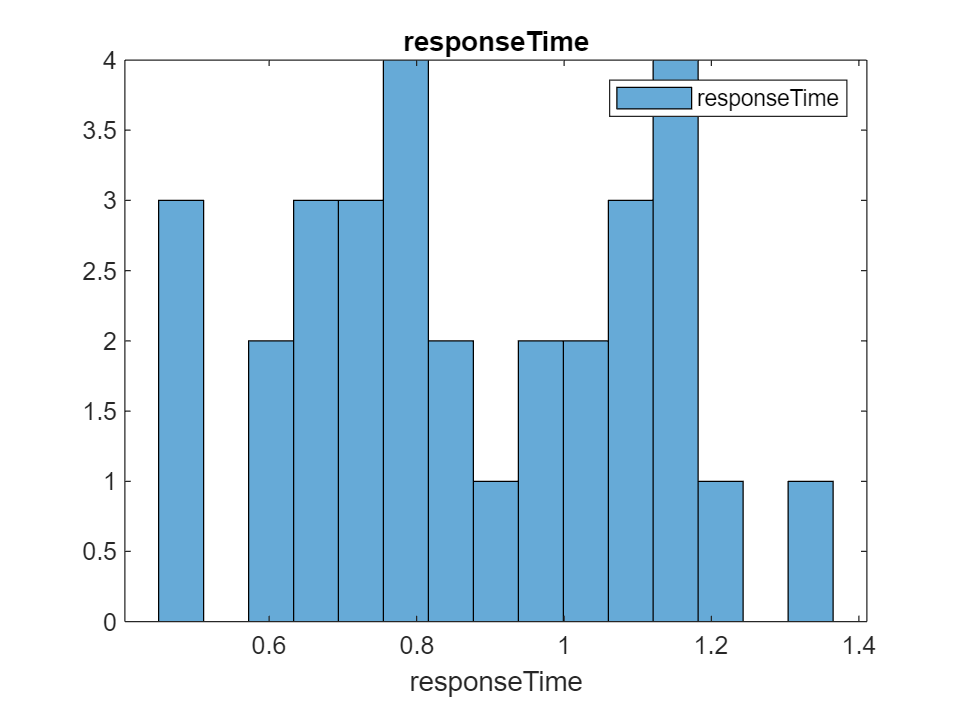

p = 0.0594

p = ranksum(matchedTrials.responseTime, unmatchedTrials.responseTime)

#### Machine learning techniques

We may want to use advanced techniques like those used in Machine Learning to analyse data, predict results or find patterns. To get started, try the Classification Learner app to predict correct answers from stimuli and resonse time.

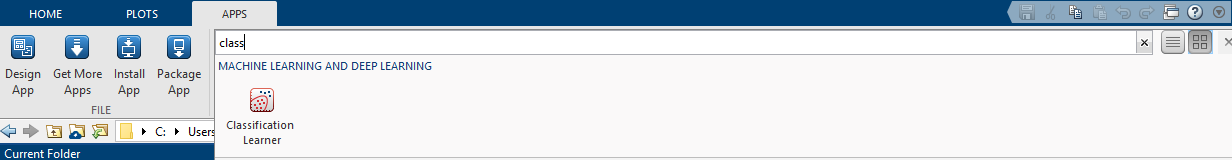

Additional information on how to find patterns in data with advanced techniques can be found in the documentation at [Choose Cluster Analysis Method - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/choose-cluster-analysis-method.html)

### What is your next analysis...

Now it is your turn. Think about interesting ways you could add here to analyse the data...